%%

% When 𝑝 = 60 and 𝑛 = 4, determine the probability of the student to select the right
% answer. Answer: 70

p = 0.6;
q = 1 - p;
n = 4;

% E – the student answers correctly
% F1 – the student knows the answer
% F2 – the student does not know the answer
% P(E) = P(E|F1)P(F1) + P(E|F2)P(F2)

p_e = 1*p + 1/n*q

p_e = 0.7000




% When 𝑝 = 70 and 𝑛 = 5, determine the probability of the student to know the answer
% when he selects the right answer. Answer: 92

p = 0.7;
q = 1 - p;
n = 5;

% E – the student answers correctly
% F1 – the student knows the answer
% F2 – the student does not know the answer
% Prob = P(F1|E)

p_e = 1*p + 1/n*q;

prob = p/p_e

prob = 0.9211

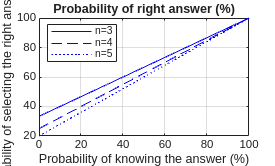



% 
% Draw a plot (with the same look as the plot below) with the probability of the student to
% select the right answer as a function of the probability 𝑝 (consider the number of multiple
% answers 𝑛 = 3, 4 and 5)


p = linspace(0,1,10);

p_e3 = 1*p + 1/3*(1-p);
p_e4 = 1*p + 1/4*(1-p);
p_e5 = 1*p + 1/5*(1-p);

figure(1)
plot(p*100,p_e3*100,'b')
hold on
plot(p*100,p_e4*100,'b--')
hold on
plot(p*100,p_e5*100,'b:')
grid on
title('Probability of right answer (%)');
xlabel('Probability of knowing the answer (%)');
ylabel('Probability of selecting the right answer (%)');
legend('n=3', 'n=4', 'n=5','Location' ,'northwest');
hold off

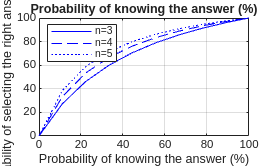



% Draw a plot (with the same look as the plot below) with the probability of the student to
% know the answer when he selects the right answer as a function of the probability 𝑝
% (consider 𝑛 = 3, 4 and 5).


p = linspace(0,1,10);

p_e3 = 1*p + 1/3*(1-p);
p_e4 = 1*p + 1/4*(1-p);
p_e5 = 1*p + 1/5*(1-p);

prob3 = p./p_e3;
prob4 = p./p_e4;
prob5 = p./p_e5;

figure(1)
plot(p*100,prob3*100,'b')
hold on
plot(p*100,prob4*100,'b--')
hold on
plot(p*100,prob5*100,'b:')
grid on
title('Probability of knowing the answer (%)');
xlabel('Probability of knowing the answer (%)');
ylabel('Probability of selecting the right answer (%)');
legend('n=3', 'n=4', 'n=5','Location' ,'northwest');
hold off